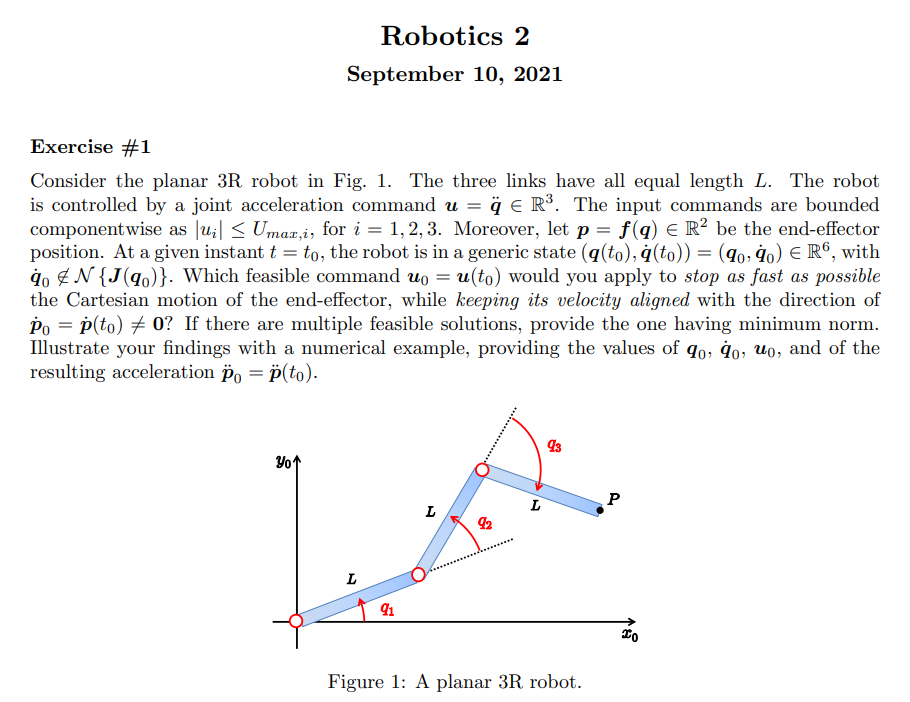

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% 

% 
% PC_EEShort.J
% PC_EEShort.f

% VarShortRobot.M
% angle_desired=[0,0]
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)

% 
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(PCVar.Pc, z.q, z.l, z.m, z.dc, z.g, z.isMotor)
% 

% U{1}
% PE_short
% g_q

% z.l_=[0.5,0.4,0.3]
% z.dc_=z.l_/2
% z.m_=[5,3,2]
% z.q_=[pi,0,-pi/2]
% to_replace=[z.l',z.dc',z.m',z.q',g0]
% to_replace_=[z.l_,z.dc_,z.m_,z.q_ ,9.8]
% f_=vpa(subs(f,to_replace,to_replace_))
% J_=vpa(subs(J,to_replace,to_replace_))
% J_ps_=vpa(subs(J_ps,to_replace,to_replace_))
% g_q_=vpa(subs(g_q,to_replace,to_replace_))
% 
% q_r_dot_= vpa(g_q_-J_ps_*J_*g_q_)


## Exercise 3

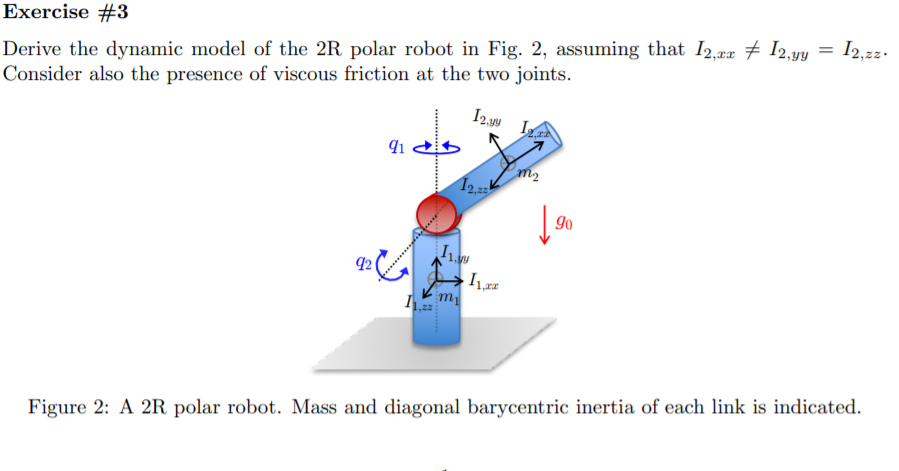

% close all
% % Lengths just to test
% d1_=10;
% d2_=10;
% a2_=10;
% % % De Luca's approach
%  links = [
%     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
%     Revolute('a', a2_, 'alpha',0,'d', 0);
% %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
%     ];
% % 
%  c600 = SerialLink(links);
%  c600.teach([0 0],'view','x');
% % c600.plot([0  pi/2 20 0],'view','x')
% clear


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,0,-g0]';

R2Robot=['rr';'zx';sigmaD]

R2Robot = 3×2 char array
    'rr'
    'zx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
% z.I=I;
z.methodD=2%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: {}
                 methodD: 2
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: {}
                 methodD: 2
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
            0       , z.l(2)  , 0   , q(2);]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: {}
                 methodD: 2
                 dhTable: [2×4 sym]
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       


%[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M] = getGenericPC2_xyz(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: {}
                 methodD: 2
                 dhTable: [2×4 sym]
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
       

si falla aquí está el error
method with DH table, pay attention!
moving frames OFF!!


$$Ti = \frac{{\mathrm{Iyy}}_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2} & \frac{{\mathrm{Izz}}_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{1}}^{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)\right)}{2}+\frac{{\mathrm{Iyy}}_{2}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ixx}}_{2}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2} \end{array}\right)$$

$$Ti = \left(\begin{array}{cc} \frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2} & \left(\frac{{\mathrm{Iyy}}_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}}{2}-\frac{{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(\frac{m_{2}\,{{\mathrm{dc}}_{2}}^{2}}{2}+\frac{{\mathrm{Izz}}_{2}}{2}\right)\,{{\dot{q}}_{2}}^{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right) & -l_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ l_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right) & -l_{2}\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\\ 0 & l_{2}\,\cos\left(q_{2}\left(t\right)\right) \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1} & l_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & {\dot{q}}_{1}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1} & {\dot{q}}_{1}\,\cos\left(q_{2}\right)\\ 0 & {\dot{q}}_{2} \end{array}\right)$$

$$T = \left(\frac{{\mathrm{Iyy}}_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}}{2}-\frac{{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(\frac{m_{2}\,{{\mathrm{dc}}_{2}}^{2}}{2}+\frac{{\mathrm{Izz}}_{2}}{2}\right)\,{{\dot{q}}_{2}}^{2}+\frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2}$$

$$Ti = \left(\begin{array}{cc} \frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2} & \left(\frac{{\mathrm{Iyy}}_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}}{2}-\frac{{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(\frac{m_{2}\,{{\mathrm{dc}}_{2}}^{2}}{2}+\frac{{\mathrm{Izz}}_{2}}{2}\right)\,{{\dot{q}}_{2}}^{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} {\mathrm{Iyy}}_{1}+{\mathrm{Iyy}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}-{\mathrm{Iyy}}_{2}\,{\sin\left(q_{2}\right)}^{2}-{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,{\sin\left(q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Izz}}_{2} \end{array}\right)$$

Pc

$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1} & l_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

vc

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))

$$ans = {{\mathrm{dc}}_{2}}^{2}\,\left(-{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}+{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)$$

Ti(1)

$$ans = \frac{{\mathrm{Iyy}}_{1}}{2}\,{{\dot{q}}_{1}}^{2}$$

Ti(2)

$$ans = \left(\frac{{\mathrm{Iyy}}_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}}{2}-\frac{{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,\left({\sin\left(q_{2}\right)}^{2}-1\right)}{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(\frac{m_{2}\,{{\mathrm{dc}}_{2}}^{2}}{2}+\frac{{\mathrm{Izz}}_{2}}{2}\right)\,{{\dot{q}}_{2}}^{2}$$

M

$$M = \left(\begin{array}{cc} {\mathrm{Iyy}}_{1}+{\mathrm{Iyy}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{\mathrm{Ixx}}_{2}\,{\sin\left(q_{2}\right)}^{2}-{\mathrm{Iyy}}_{2}\,{\sin\left(q_{2}\right)}^{2}-{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,{\sin\left(q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Izz}}_{2} \end{array}\right)$$

[Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

>> Getting dynamic coefficients. Might take a while...


paramscell2 = 1×3 cell array
    {1×1 cell}    {1×2 cell}    {1×3 cell}


MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{cc} {\mathrm{aa}}_{5}+{\mathrm{aa}}_{2}\,{\sin\left(q_{2}\right)}^{2}+{\mathrm{aa}}_{3}\,{\sin\left(q_{2}\right)}^{2}+{\mathrm{aa}}_{4}\,{\sin\left(q_{2}\right)}^{2} & 0\\ 0 & {\mathrm{aa}}_{1} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{cc} a_{1}\,{\sin\left(q_{2}\right)}^{2}+a_{3} & 0\\ 0 & a_{2} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} -m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Ixx}}_{2}-{\mathrm{Iyy}}_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Izz}}_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Iyy}}_{1}+{\mathrm{Iyy}}_{2} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

Msubs

$$Msubs = \left(\begin{array}{cc} a_{1}\,{\sin\left(q_{2}\right)}^{2}+a_{3} & 0\\ 0 & a_{2} \end{array}\right)$$

% 

% PC_EEShort.J
% PC_EEShort.f

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

$$PE\_short = g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

U = 1×2 cell array
    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$PE\_short = g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

[C,cac,Csubs] = getCs(Msubs,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} a_{1}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(2\,q_{2}\right)\\ -\frac{a_{1}\,{{\dot{q}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)}{2} \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


cac

$$cac = \left(\begin{array}{c} -{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}-{\mathrm{Ixx}}_{2}+{\mathrm{Iyy}}_{2}\right)\\ \frac{{{\dot{q}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}-{\mathrm{Ixx}}_{2}+{\mathrm{Iyy}}_{2}\right)}{2} \end{array}\right)$$

g_q

$$g\_q = \left(\begin{array}{c} 0\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

U{:}

$$ans = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}$$

$$ans = g_{0}\,m_{2}\,\left(l_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\right)$$

F_v=sym('F',[2,1],'real')

$$F\_v = \left(\begin{array}{c} F_{1}\\ F_{2} \end{array}\right)$$

[All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

>> Getting dynamic coefficients. Might take a while...


paramscell2 = 1×6 cell array
    {1×1 cell}    {1×1 cell}    {1×1 cell}    {1×2 cell}    {1×3 cell}    {1×3 cell}


MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{ccccc} {\mathrm{aa}}_{8}+{\mathrm{aa}}_{2}\,{\sin\left(q_{2}\right)}^{2}+{\mathrm{aa}}_{4}\,{\sin\left(q_{2}\right)}^{2}+{\mathrm{aa}}_{7}\,{\sin\left(q_{2}\right)}^{2} & 0 & 0 & 0 & {\mathrm{aa}}_{5}\\ 0 & {\mathrm{aa}}_{1} & 0 & {\mathrm{aa}}_{3}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{6} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$All = \left(\begin{array}{ccccc} a_{1}\,{\sin\left(q_{2}\right)}^{2}+a_{5} & 0 & 0 & 0 & a_{3}\\ 0 & a_{2} & 0 & a_{6}\,g_{0}\,\cos\left(q_{2}\right) & a_{4} \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} -m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Ixx}}_{2}-{\mathrm{Iyy}}_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Izz}}_{2}\\ F_{1}\\ F_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+{\mathrm{Iyy}}_{1}+{\mathrm{Iyy}}_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5}\\ a_{6} \end{array}\right)$$

%complete model
Msubs*z.q_ddot+cac+F_v'*z.q_dot%=Tao

$$ans = \left(\begin{array}{c} F_{1}\,{\dot{q}}_{1}+F_{2}\,{\dot{q}}_{2}+{\ddot{q}}_{1}\,\left(a_{1}\,{\sin\left(q_{2}\right)}^{2}+a_{3}\right)+a_{1}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(2\,q_{2}\right)\\ -\frac{a_{1}\,\sin\left(2\,q_{2}\right)\,{{\dot{q}}_{1}}^{2}}{2}+F_{1}\,{\dot{q}}_{1}+F_{2}\,{\dot{q}}_{2}+a_{2}\,{\ddot{q}}_{2} \end{array}\right)$$